# Business Statistics and Data Analytics

## Overview of Data Analytics

Data analytics turns a business records into decisions. It is a pipeline, not a single calculation. Each stage changes the table the next stage sees.

A conclusion can never be better than the table it was computed from, which is why cleaning takes up most of this script.

## Workflow of Data Analytics

- **Import** — read the file and declare what each column means

- **Assess** — measure what is wrong before changing anything

- **Clean** — duplicates, inconsistent text, missing values, outliers

- **Explore** — chart the data to answer business questions

- **Conclude** — state what to act on

## Import the Raw Data

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 7);

% Specify sheet and range
opts.Sheet = "online_retail_demo";
opts.DataRange = "A2:G409";

% Specify column names and types
opts.VariableNames = ["OrderID", "CustomerID", "ProductType", "Brand", "Country", ...
    "OrderDate", "UnitPrice"];
opts.VariableTypes = ["string", "double", "categorical", "categorical", "categorical", ...
    "datetime", "double"];

% Specify variable properties
opts = setvaropts(opts, "OrderID", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["OrderID", "ProductType", "Brand", "Country"], "EmptyFieldRule", ...
    "auto");

% Import the data
rawData = readtable(".\online_retail_demo.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
rawData

rawData = 408×7 table
      OrderID      CustomerID         ProductType             Brand           Country         OrderDate     UnitPrice
    ___________    __________    ______________________    ____________    ______________    ___________    _________

    "DEMO-0001"       4286       Dark Chocolate Bar        <undefined>     United Kingdom    16-Sep-2024      15.85  
    "DEMO-0002"       7855       Our Salted Pretzels       SnackWorks      United Kingdom    09-May-2024       17.8  
    "DEMO-0003"       9676       Our Almond Butter Cups    (NuttyBite)     United Kingdom    03-Sep-2025      24.46  
    "DEMO-0004"       8670       Salted Pretzels           (PurePantry)    France            08-Jul-2024       17.2  
    "DEMO-0005"       6356     

### What do we see from this table?

### Assess Data

summary(rawData)


rawData: 408×7 table

Variables:

    OrderID: string
    CustomerID: double
    ProductType: categorical (34 categories)
    Brand: categorical (30 categories)
    Country

#### What do we see from data summary?

## Data Cleaning

every cleaning step is check, fix, confirm. The confirm step matters most

### Remove Duplicate Order

one order ID means one sale. A repeated ID counts the same sale twice and inflates every total that follows.

#### Check

Compare the number of unique order IDs with the number of rows; the gap is the number of duplicates.

preData = rawData;
unique(preData.OrderID)

ans = 400×1 string array
    "DEMO-0001"
    "DEMO-0002"
    "DEMO-0003"
    "DEMO-0004"
    "DEMO-0005"
    "DEMO-0006"
    "DEMO-0007"
    "DEMO-0008"
    "DEMO-0009"
    "DEMO-0010"
    "DEMO-0011"
    "DEMO-0012"
    "DEMO-0013"
    "DEMO-0014"
    "DEMO-0015"
    "DEMO-0016"
    "DEMO-0017"
    "DEMO-0018"
    "DEMO-0019"
    "DEMO-0020"
    "DEMO-0021"
    "DEMO-0022"
    "DEMO-0023"
    "DEMO-0024"
    "DEMO-0025"
    "DEMO-0026"
    "DEMO-0027"
    "DEMO-0028"
    "DEMO-0029"
    "DEMO-0030"


#### Remove  & Confirm

`unique` with `"stable"` returns the first appearance of each ID and keeps the rows in their original order. Indexing with `keepIdx` is what removes the duplicates.

[~, keepIdx] = unique(preData.OrderID, "stable");
preData = preData(keepIdx,:);
summary(preData.OrderID)


400×1 string

    NumMissing      0  



### Clean Text

labels that mean the same thing must be spelled the same way before they can be counted. Text cleaning in MATLAB always follows one shape — tokenize, transform, rejoin.

Change the variable type for preprocessing 

preData.CustomerID = string(preData.CustomerID);
preData.ProductType = string(preData.ProductType);
preData.Brand = string(preData.Brand);

#### Clean ProductType

check unique entry

unique(preData.ProductType)

ans = 34×1 string array
    "Almond Butter Cups"
    "Cocoa Wafers"
    "Dark Chocolate Bar"
    "Fruit Gummies"
    "Granola Mix"
    "Our Almond Butter Cups"
    "Our Cocoa Wafers"
    "Our Dark Chocolate Bar"
    "Our Fruit Gummies"
    "Our Granola Mix"
    "Our Rice Crackers"
    "Our Salted Pretzels"
    "Our Sea Salt Chips"
    "Rice Crackers"
    "Salted Pretzels"
    "Sea Salt Chips"
    "The Almond Butter Cups"
    "The Cocoa Wafers"
    "The Dark Chocolate Bar"
    "The Fruit Gummies"
    "The Granola Mix"
    "The Rice Crackers"
    "The Salted Pretzels"
    "The Sea Salt Chips"
    "These Almond Butter Cups"
    "These Cocoa Wafers"
    "These Fruit Gummies"
    "These Rice Crackers"
    "These Salted Pretzels"
    "These Sea Salt Chips"


Preprocess Live Task

%% Preprocess Text
product = preData.ProductType;

% Tokenize
product = tokenizedDocument(product);

% Change and remove words
product = normalizeWords(product,Style="lemma");
product = removeStopWords(product,IgnoreCase=true);

% Display results
display(product);

product =   400×1 tokenizedDocument:

    3 tokens: dark chocolate bar
    2 tokens: salt pretzel
    3 tokens: almond butter cup
    2 tokens: salt pretzel
    2 tokens: cocoa wafer
    2 tokens: cocoa wafer
    3 tokens: dark chocolate bar
    3 tokens: sea salt chip
    2 tokens: salt pretzel
    2 tokens: rice cracker
    3 tokens: almond butter cup
    2 tokens: cocoa wafer
    2 tokens: salt pretzel
    3 tokens: sea salt chip
    2 tokens: granola mix
    2 tokens: salt pretzel
    2 tokens: granola mix
    2 tokens: cocoa wafer
    2 tokens: rice cracker
    2 tokens: granola mix
    2 tokens: salt pretzel
    2 tokens: rice cracker
    2 tokens: cocoa wafer
    3 tokens: almond butter cup
    3 tokens: dark chocolate bar
    2 tokens: rice cracker
    3 tokens: dark chocolate bar
    2 tokens: granola mix
    2 tokens: salt pretzel
    2 tokens: salt pretzel
    2 tokens: salt pretzel
    2 tokens: co

convert the tokenized text to string and check unique entry

product = joinWords(product);
unique(product)

ans = 8×1 string array
    "almond butter cup"
    "cocoa wafer"
    "dark chocolate bar"
    "fruit gummies"
    "granola mix"
    "rice cracker"
    "salt pretzel"
    "sea salt chip"


change the variable type to categorical for later analysis

preData.ProductType = categorical(product);

#### Clean Brand

check unique entry

unique(preData.Brand)

ans = 70×1 string array
    "(ChocoDeluxe)"
    "(GoldenGrain)"
    "(NuttyBite)"
    "(PurePantry)"
    "(SnackWorks)"
    "Choco-Deluxe"
    "ChocoDeluxe"
    "ChocoDeluxe!"
    "ChocoDeluxe,"
    "ChocoDeluxe."
    "Golden-Grain"
    "GoldenGrain"
    "GoldenGrain!"
    "GoldenGrain,"
    "GoldenGrain."
    "Nutty-Bite"
    "NuttyBite"
    "NuttyBite!"
    "NuttyBite,"
    "NuttyBite."
    "Pure-Pantry"
    "PurePantry"
    "PurePantry!"
    "PurePantry,"
    "PurePantry."
    "Snack-Works"
    "SnackWorks"
    "SnackWorks!"
    "SnackWorks,"
    "SnackWorks."


Preprocess Live Task

%% Preprocess Text
brand = preData.Brand;

% Tokenize
brand = tokenizedDocument(brand);

% Add token details
brand = addPartOfSpeechDetails(brand);

% Change and remove words
brand = erasePunctuation(brand);

% Display results
display(brand);

brand =   400×1 tokenizedDocument:

    0 tokens:
    1 tokens: SnackWorks
    1 tokens: NuttyBite
    1 tokens: PurePantry
    1 tokens: PurePantry
    0 tokens:
    1 tokens: ChocoDeluxe
    1 tokens: SnackWorks
    1 tokens: GoldenGrain
    1 tokens: ChocoDeluxe
    1 tokens: NuttyBite
    1 tokens: ChocoDeluxe
    1 tokens: ChocoDeluxe
    1 tokens: ChocoDeluxe
    1 tokens: GoldenGrain
    0 tokens:
    1 tokens: PurePantry
    0 tokens:
    1 tokens: GoldenGrain
    1 tokens: GoldenGrain
    1 tokens: SnackWorks
    1 tokens: GoldenGrain
    1 tokens: ChocoDeluxe
    1 tokens: PurePantry
    1 tokens: GoldenGrain
    1 tokens: GoldenGrain
    1 tokens: GoldenGrain
    1 tokens: SnackWorks
    1 tokens: NuttyBite
    1 tokens: SnackWorks
    1 tokens: SnackWorks
    1 tokens: SnackWorks
    1 tokens: GoldenGrain
    1 tokens: ChocoDeluxe
    0 tokens:
    1 tokens: ChocoDeluxe
    1 tokens: GoldenGrain
  

convert the tokenized text to string and check unique entry

brand = joinWords(brand);
unique(brand)

ans = 6×1 string array
    ""
    "ChocoDeluxe"
    "GoldenGrain"
    "NuttyBite"
    "PurePantry"
    "SnackWorks"


change the variable type to categorical for later analysis

preData.Brand = categorical(brand);

### Fill Missing Values

There are 2 columns that have missing values `Brand and UnitPrice. `Before filling any missing value, we have to

- Detect the missing value

- Diagnose the data - Is there a pattern?

- Pick the strategy

- Delete

- Fill with mean/median/mode or constant

- Group-based 

#### Fill missing Brand

Detect

missIdx = ismissing(preData.Brand);
missBrand = preData(missIdx,:)

missBrand = 40×7 table
      OrderID      CustomerID          ProductType              Brand          Country         OrderDate     UnitPrice
    ___________    __________    ________________________    ___________    ______________    ___________    _________

    "DEMO-0001"      "4286"      "Dark Chocolate Bar"        <undefined>    United Kingdom    16-Sep-2024      15.85  
    "DEMO-0006"      "9694"      "Cocoa Wafers"              <undefined>    France            05-Mar-2024      24.92  
    "DEMO-0016"      "6997"      "Our Salted Pretzels"       <undefined>    United Kingdom    03-Oct-2024      24.87  
    "DEMO-0018"      "5939"      "The Cocoa Wafers"          <undefined>    France            25-Dec-2025      21.92  
    "DEMO-0035"      "13

Diagnose the missing Brand

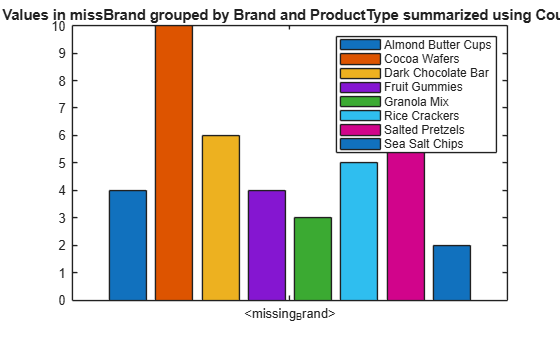

% Create pivoted table
pivot_missbrand = pivot(missBrand, Rows="Brand", Columns="ProductType", ...
    RowLabelPlacement="rownames");

% Generate grouped bar graph
colNames4 = pivot_missbrand.Properties.VariableNames;
bar(pivot_missbrand,"Row",colNames4,Interpreter="none");
legend(Interpreter="none");
title("Values in missBrand grouped by Brand and ProductType summarized using Count");
xlabel("");


clear colNames4

Check the common Brand-ProductType

% Compute group summary
productbrand = groupsummary(preData,"ProductType","mode","Brand");
productbrand.GroupCount = []

productbrand = 8×2 table
       ProductType        mode_Brand 
    __________________    ___________

    Almond Butter Cups    NuttyBite  
    Cocoa Wafers          ChocoDeluxe
    Dark Chocolate Bar    ChocoDeluxe
    Fruit Gummies         PurePantry 
    Granola Mix           GoldenGrain
    Rice Crackers         GoldenGrain
    Salted Pretzels       SnackWorks 
    Sea Salt Chips        SnackWorks 

	Get insights using Copilot


Fill missing Brand with the common Brand of each ProductType

First, check the product type of missing brand

preData.ProductType(missIdx)

ans = 40×1 categorical array
     Dark Chocolate Bar 
     Cocoa Wafers 
     Salted Pretzels 
     Cocoa Wafers 
     Fruit Gummies 
     Rice Crackers 
     Salted Pretzels 
     Rice Crackers 
     Salted Pretzels 
     Almond Butter Cups 
     Fruit Gummies 
     Dark Chocolate Bar 
     Dark Chocolate Bar 
     Rice Crackers 
     Almond Butter Cups 
     Cocoa Wafers 
     Salted Pretzels 
     Dark Chocolate Bar 
     Almond Butter Cups 
     Rice Crackers 
     Sea Salt Chips 
     Dark Chocolate Bar 
     Cocoa Wafers 
     Cocoa Wafers 
     Cocoa Wafers 
     Cocoa Wafers 
     Cocoa Wafers 
     Almond Butter Cups 
     Fruit Gummies 
     Cocoa Wafers 


Then, find the index of the product type of missing brand that match the Brand-ProductType table

[~, loc] = ismember(preData.ProductType(missIdx), productbrand.ProductType)

loc =      3
     2
     7
     2
     4
     6
     7
     6
     7
     1
     4
     3
     3
     6
     1


fill the missing brand with the common brand of each product type

preData.Brand(missIdx) = productbrand.mode_Brand(loc)

preData = 400×7 table
      OrderID      CustomerID       ProductType           Brand          Country         OrderDate     UnitPrice
    ___________    __________    __________________    ___________    ______________    ___________    _________

    "DEMO-0001"      "4286"      Dark Chocolate Bar    ChocoDeluxe    United Kingdom    16-Sep-2024      15.85  
    "DEMO-0002"      "7855"      Salted Pretzels       SnackWorks     United Kingdom    09-May-2024       17.8  
    "DEMO-0003"      "9676"      Almond Butter Cups    NuttyBite      United Kingdom    03-Sep-2025      24.46  
    "DEMO-0004"      "8670"      Salted Pretzels       PurePantry     France            08-Jul-2024       17.2  
    "DEMO-0005"      "6356"      Cocoa Wafers          PurePa

check the summary

summary(preData.Brand)


400×1 categorical

     ChocoDeluxe      90 
     GoldenGrain      95 
     NuttyBite        59 
     PurePantry       67 
     SnackWorks       89 
     <undefined>       0 


#### Fill missing UnitPrice

Detect the missing UnitPrice and Diagnose

missIdx = ismissing(preData.UnitPrice);
preData(missIdx,:)

ans = 15×7 table
      OrderID      CustomerID       ProductType           Brand          Country         OrderDate     UnitPrice
    ___________    __________    __________________    ___________    ______________    ___________    _________

    "DEMO-0024"      "5439"      Almond Butter Cups    PurePantry     Belgium           26-Jul-2024       NaN   
    "DEMO-0070"      "3053"      Salted Pretzels       SnackWorks     France            10-Dec-2024       NaN   
    "DEMO-0071"      "4305"      Dark Chocolate Bar    ChocoDeluxe    United Kingdom    22-Dec-2025       NaN   
    "DEMO-0094"      "7855"      Sea Salt Chips        NuttyBite      United Kingdom    19-Feb-2024       NaN   
    "DEMO-0160"      "9634"      Fruit Gummies         PurePantry 

Check the data distribution to pick the right strategy

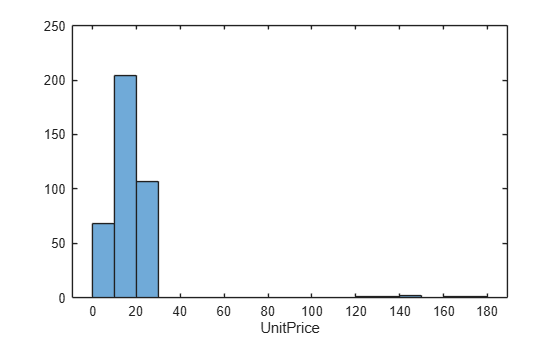

% Create histogram of UnitPrice
hPrice = histogram(preData,"UnitPrice","DisplayName","UnitPrice");

Clean Outlier UnitPrice

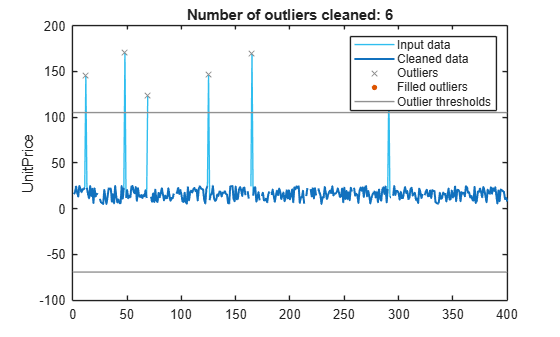

% Fill outliers
[clData,outlierIndices,lo,hi] = filloutliers(preData,NaN,"mean", ...
    ThresholdFactor=5,DataVariables="UnitPrice");

% Display results
figure
plot(preData.UnitPrice,SeriesIndex=6,DisplayName="Input data")
hold on
plot(clData.UnitPrice,SeriesIndex=1,LineWidth=1.5,DisplayName="Cleaned data")

% Plot outliers
plot(find(outlierIndices(:,7)),preData.UnitPrice(outlierIndices(:,7)),"x", ...
    Color=[145 145 145]/255,DisplayName="Outliers")

% Plot filled outliers
plot(find(outlierIndices(:,7)),clData.UnitPrice(outlierIndices(:,7)),".", ...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled outliers")

% Plot outlier thresholds
plot([xlim missing xlim], ...
    [lo.UnitPrice lo.UnitPrice missing hi.UnitPrice hi.UnitPrice], ...
    Color=[145 145 145]/255,DisplayName="Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices(:,7)))
legend
ylabel("UnitPrice")

clear lo hi

Check UnitPrice distribution again

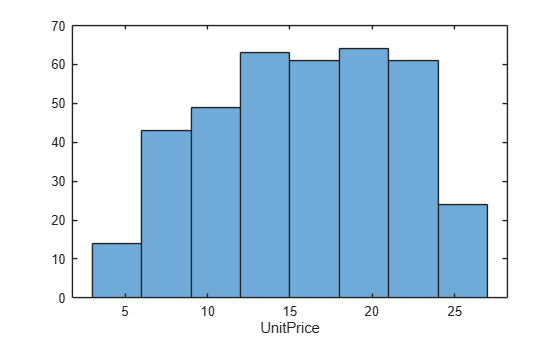

% Create histogram of UnitPrice
hPrice = histogram(clData,"UnitPrice","DisplayName","UnitPrice");

Replace missing UnitPrice values with the median cleaned price

missPriceIdx = ismissing(clData.UnitPrice);
clData.UnitPrice(missPriceIdx) = median(clData.UnitPrice,"omitmissing");
summary(clData.UnitPrice)


400×1 double

    NumMissing            0  
    Min              5.0600  
    Median          16.1200  
    Max             24.9700  
    Mean            15.8225  
    Std              5.4444  



## Business Exploratory Data Analysis (EDA)

**Goal**: understand the data before making decisions, and start exploring business relationships.

### How is the Sales in each Country?

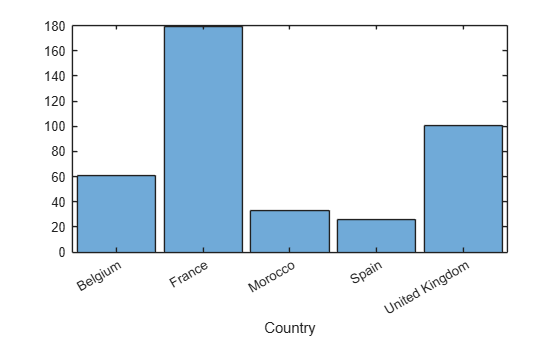

% Create histogram of Country
h = histogram(clData,"Country","DisplayName","Country");

### Which product type sells most?

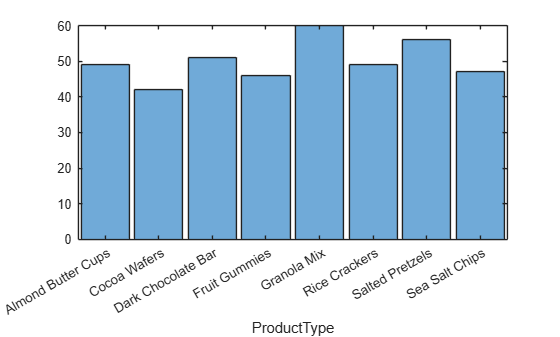

% Create histogram of ProductType
h2 = histogram(clData,"ProductType","DisplayName","ProductType");

### What is the dominant product type of each brand?

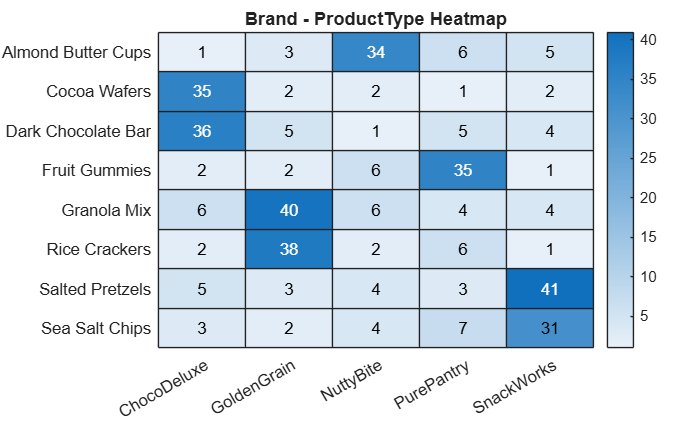

% Create pivoted table
pivotedData = pivot(clData, Rows="ProductType", Columns="Brand", ...
    RowLabelPlacement="rownames");

% Generate heatmap chart
rowNames = pivotedData.Properties.RowNames;
colNames = pivotedData.Properties.VariableNames;
data = table2array(pivotedData);
heatmap(colNames,rowNames,data, Interpreter="none", ...
    Title="Values in clData grouped by ProductType and Brand summarized using Count");


clear rowNames colNames data

### How does brand preference vary across countries?

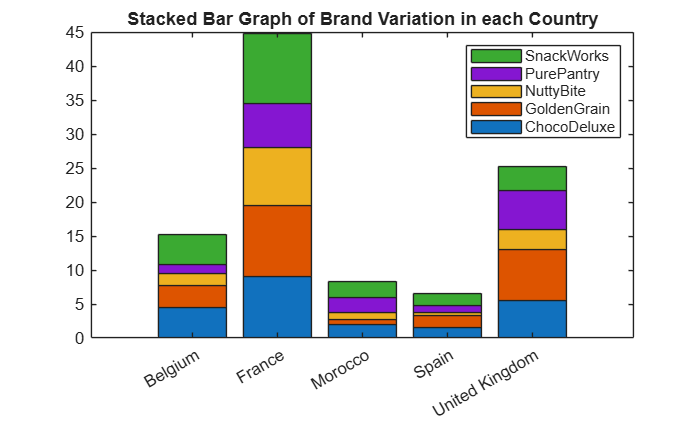

% Create pivoted table
pivotedData2 = pivot(clData, Rows="Country", Columns="Brand", ...
    Method="percentage", RowLabelPlacement="rownames");

% Generate stacked bar graph
colNames2 = pivotedData2.Properties.VariableNames;
bar(pivotedData2,"Row",colNames2,BarLayout="stacked",Interpreter="none");
legend(Interpreter="none");
title("Values in clData grouped by Country and Brand summarized using Percentage");
xlabel("");


clear colNames2

### How does product type preference vary across countries?

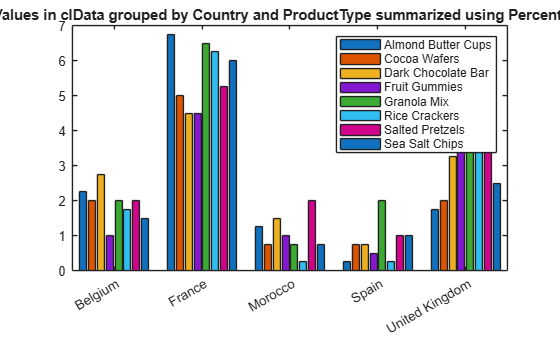

% Create pivoted table
pivotedData3 = pivot(clData, Rows="Country", Columns="ProductType", ...
    Method="percentage", RowLabelPlacement="rownames");

% Generate grouped bar graph
colNames3 = pivotedData3.Properties.VariableNames;
bar(pivotedData3,"Row",colNames3,Interpreter="none");
legend(Interpreter="none");
title("Values in clData grouped by Country and ProductType summarized using Percentage");
xlabel("");


clear colNames3

### What is our revenue?

% Compute group summary
revenue = groupsummary(clData,"OrderDate","month","sum","UnitPrice");
revenue.GroupCount = []

revenue = 24×2 table
    month_OrderDate    sum_UnitPrice
    _______________    _____________

       Jan-2024           305.92    
       Feb-2024           113.21    
       Mar-2024           209.04    
       Apr-2024           143.05    
       May-2024           359.89    
       Jun-2024           161.51    
       Jul-2024           387.26    
       Aug-2024           136.46    
       Sep-2024           227.99    
       Oct-2024           178.89    
       Nov-2024           342.85    
       Dec-2024           166.28    
       Jan-2025           117.77    
       Feb-2025           234.61    
       Mar-2025           278.42    
       Apr-2025           419.65    

	Get insights using Copilot


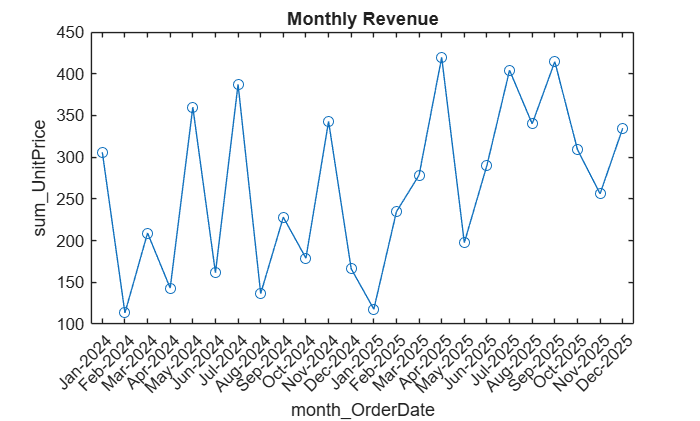

% Create plot of selected data
sale = plot(revenue,"month_OrderDate","sum_UnitPrice","Marker","o","DisplayName","sum_UnitPrice");

% Add xlabel, ylabel, title, and legend
xlabel("month_OrderDate")
ylabel("sum_UnitPrice")
title("sum_UnitPrice vs. month_OrderDate")
legend

### How much our top spender spends?

% Compute group summary
customer = groupsummary(clData,"CustomerID",["sum","mean"],"UnitPrice")

customer = 90×4 table
    CustomerID    GroupCount    sum_UnitPrice    mean_UnitPrice
    __________    __________    _____________    ______________

      "1046"          6            108.92            18.153    
      "1210"          3             47.77            15.923    
      "1232"          2             42.85            21.425    
      "1268"          5             91.78            18.356    
      "1355"          1             22.03             22.03    
      "1390"          3             38.32            12.773    
      "1598"          5             72.44            14.488    
      "1610"          1             15.56             15.56    
      "1651"          3             51.09             17.03    
      "1748"          2             37.93            18.965    
      "1788"          1             24.28             24.28    
      "19

customer_top10spend = sortrows(customer,"sum_UnitPrice","descend");
customer_top10spend = customer_top10spend(1:10,:);
customer_top10spend.CustomerID = categorical(customer_top10spend.CustomerID,customer_top10spend.CustomerID)

customer_top10spend = 10×4 table
    CustomerID    GroupCount    sum_UnitPrice    mean_UnitPrice
    __________    __________    _____________    ______________

       8670           26           359.54            13.828    
       7855           16           260.81            16.301    
       9676           14           234.76            16.769    
       4144           13           229.44            17.649    
       5267           17           214.82            13.426    
       9694            9            181.1            20.122    
       3479           12           180.19            15.016    
       8858           10           166.16            16.616    
       6151            8           139.47            17.434    
       4286            8            135.9            16.988    

	

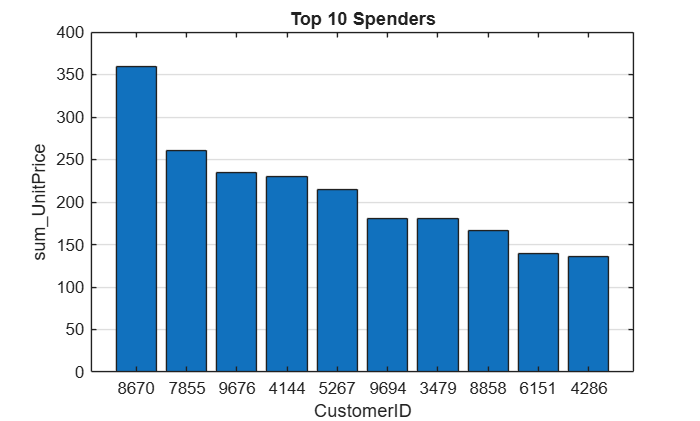

% Create bar of selected data
b = bar(customer_top10spend,"CustomerID","sum_UnitPrice","DisplayName","sum_UnitPrice");

% Add xlabel, ylabel, title, and legend
xlabel("CustomerID")
ylabel("sum_UnitPrice")
title("sum_UnitPrice vs. CustomerID")
legend